# Running calciumImagingAnalysis (CIAPKG) imaging analysis via the command line

Below is an example `cacliumImagingAnalysis` pipeline using the command line for users that do not want to use the calciumImagingAnalysis class or want to create their own custom batch analyses.

All sections marked "USER INTERFACE" indicate that a GUI will appear to view processed movie, conduct cell sorting, or other interface.


% Below is an example `cacliumImagingAnalysis` pipeline using the command line for users that do not want to use the calciumImagingAnalysis class or want to create their own custom batch analyses.
	% It assumes you have already run `example_downloadTestData` to download the example test data.
	% It will also run cross-day matching at the end.
	% All sections marked "USER INTERFACE" indicate that a GUI will appear to view processed movie, conduct cell sorting, or other interface.
% Changelog
	% 2020.09.15 [19:54:14] - Use ciapkg.getDir() to make sure demo always calls correct path regardless of where user is pointing. Also make playMovie calls have titles to make clearer to new users and allow a GUI-less option.
	% 2020.09.23 [08:35:58] - Updated to add support for cross-session analysis and use ciapkg.demo.runPreprocessing() to process the other imaging sessions.
	% 2020.10.17 [19:30:01] - Update to use ciapkg.signal_extraction.runPcaIca for PCA-ICA to make easier for users to run in the future.
	% 2021.01.17 [21:38:55] - Updated to show detrend example
	% 2021.06.20 [16:04:42] - Added CNMF/CNMF-e and EXTRACT to cell extraction examples.
	% 2021.06.22 [09:20:06] - Updated to make NWB saving, etc. smoother.
	% 2021.08.10 [09:57:36] - Updated to handle CIAtah v4.0 switch to all functions inside ciapkg package.


CIATAH depends on several toolboxes. Check for dependencies before proceeding and install required toolboxes (if needed).

ciapkg.io.matlabToolboxCheck();

Required toolboxes (if warning appears, fix or install requested toolbox).
Toolbox license available and toolbox is installed! Parallel Computing Toolbox (Distrib_Computing_Toolbox).
Toolbox license available and toolbox is installed! Image Processing Toolbox (Image_Toolbox).
Toolbox license available and toolbox is installed! Signal Processing Toolbox (Signal_Toolbox).
Toolbox license available and toolbox is installed! Statistics and Machine Learning Toolbox (Statistics_Toolbox).
 
2nd tier toolbox check (not required for main pre-processing pipeline).
Toolbox license available and toolbox is installed! Computer Vision Toolbox (Video_and_Image_Blockset).
Toolbox license available and toolbox is installed! Bioinformatics Toolbox (Bioinformatics_Toolbox).
Toolbox license available and toolbox is installed! Financial Toolbox (Financial_Toolbox).
Toolbox license available and toolbox is installed! Deep Learning Toolbox (Neural_Network_Toolbox).


## Initialize

guiEnabled = 1;
saveAnalysis = 1;
inputDatasetName = '/1';
rawFileRegexp = 'concat';

% Setup folder paths
analysisFolderPath = [ciapkg.getDir() filesep 'data' filesep '2014_04_01_p203_m19_check01'];
[~,folderName,~] = fileparts(analysisFolderPath);
% Setup NWB folder paths
nwbFilePath = [analysisFolderPath filesep 'nwbFiles' filesep folderName];
nwbFileFolderPath = [analysisFolderPath filesep 'nwbFiles'];

% Load CIAtah functions
ciapkg.loadBatchFxns();

Folders still need to be removed.
ImageJ already loaded!
Skipping loading of Miji.


## Download test data, only a single session

ciapkg.api.example_downloadTestData('downloadExtraFiles',0);

Already downloaded /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/concat_recording_20140401_180333.h5


## Load movie to analyze

inputMoviePath = ciapkg.api.getFileList(analysisFolderPath,rawFileRegexp,'sortMethod','natural');
% inputMoviePath = [analysisFolderPath filesep 'concat_recording_20140401_180333.h5'];
inputMovie = ciapkg.api.loadMovieList(inputMoviePath,'inputDatasetName',inputDatasetName);

###
Getting movie info for 1\1: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/concat_recording_20140401_180333.h5
loading chunk | offset: 0  0  1 | block: 250  241    1
movie size: 0.11492Mb | 250  241 | uint16
checking movies: 100|
-------
pre-allocating uint16 zeros matrix: 250   241  3000
-------
loading 1/1: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/concat_recording_20140401_180333.h5
movie class: uint16
movie size: 250   241  3000
x-dims: 250
y-dims: 241
z-dims: 3000
movie size: 344.7532Mb | 250   241  3000 | uint16
Elapsed time is 2.904088 seconds.
###


## USER INTERFACE Visualize slice of the movie

\texttt{}
\texttt{\underline{Mouse scroll wheel}: Forward/back frame
\underline{Mouse middle-click}: pause/play movie}
\texttt{\underline{+/-}:Increase/decrease fps
\underline{Right/left arrows}:+1 or -1 frame}
\texttt{\underline{1/2}: Decrease/Increase movie sub-sample
\underline{E}: Exit}



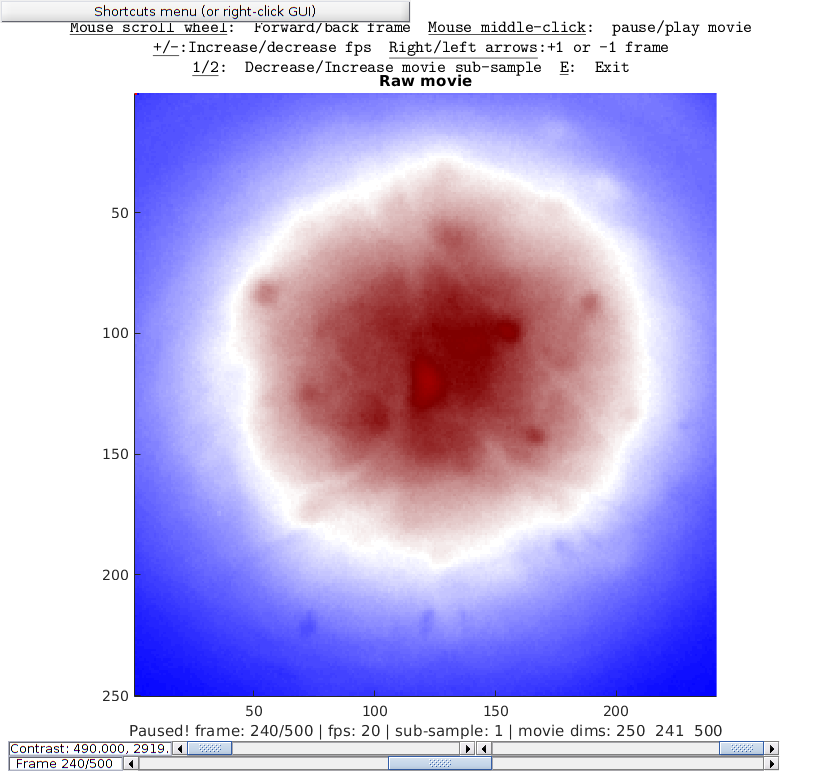

Index exceeds the number of array elements. Index must not exceed 2.

Error in ciapkg.view.playMovie (line 172)
			nFramesOriginal = inputMovieDims(3);		

Error in ciapkg.api.playMovie (line 2)
	[exitSignal, ostruct] = ciapkg.view.playMovie(inputMovie,'passArgs', varargin);

if guiEnabled==1
	ciapkg.api.playMovie(inputMovie(:,:,1:500),'extraTitleText','Raw movie');
	% Alternatively, visualize by entering the file path
	ciapkg.api.playMovie(inputMoviePath,'extraTitleText','Raw movie directly from file');
end

## USER INTERFACE Downsample input movie if need to

bilinear spatially downsampling matrix: 0|3|7|10|13|17|20|23|27|30|33|37|40|43|47|50|53|57|60|63|67|70|73|77|80|83|87|90|93|97|100
 


\texttt{}
\texttt{\underline{Mouse scroll wheel}: Forward/back frame
\underline{Mouse middle-click}: pause/play movie}
\texttt{\underline{+/-}:Increase/decrease fps
\underline{Right/left arrows}:+1 or -1 frame}
\texttt{\underline{1/2}: Decrease/Increase movie sub-sample
\underline{E}: Exit}



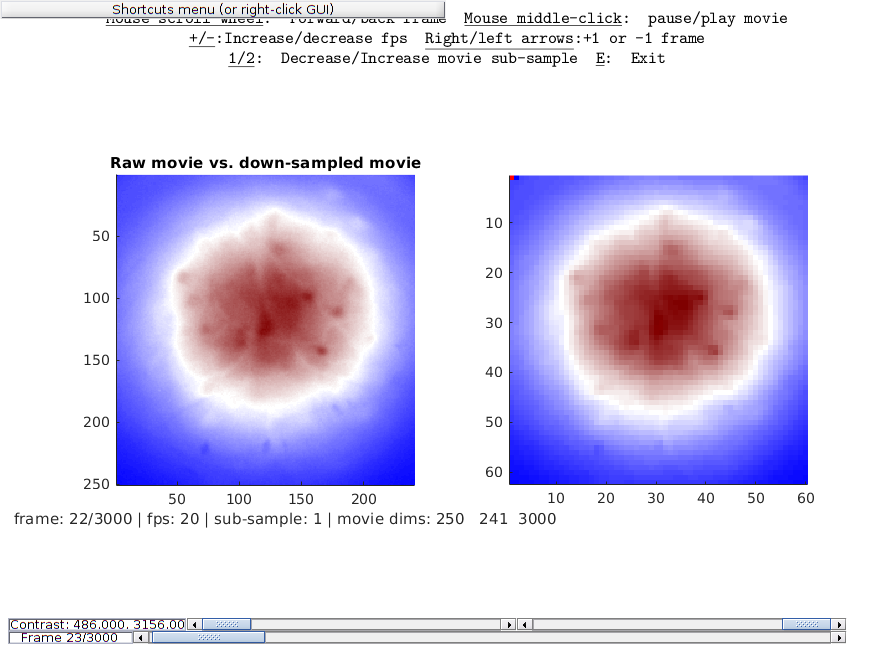

if guiEnabled==1
	inputMovieD = ciapkg.api.downsampleMovie(inputMovie,'downsampleDimension','space','downsampleFactor',4);
	ciapkg.api.playMovie(inputMovie,'extraMovie',inputMovieD,'extraTitleText','Raw movie vs. down-sampled movie');
end

## Alternatively, if you have Inscopix ISXD files, downsample by reading segments from disk using.

moviePath = 'PATH_TO_ISXD';
opts.maxChunkSize = 5000; % Max chunk size in Mb to load into RAM.
opts.downsampleFactor = 4; % How much to downsample original movie, set to 1 for no downsampling.
ciapkg.api.convertInscopixIsxdToHdf5(moviePath,'options',opts);

## Remove stripes from movie if needed

Running stripe removal using Matlab FFT


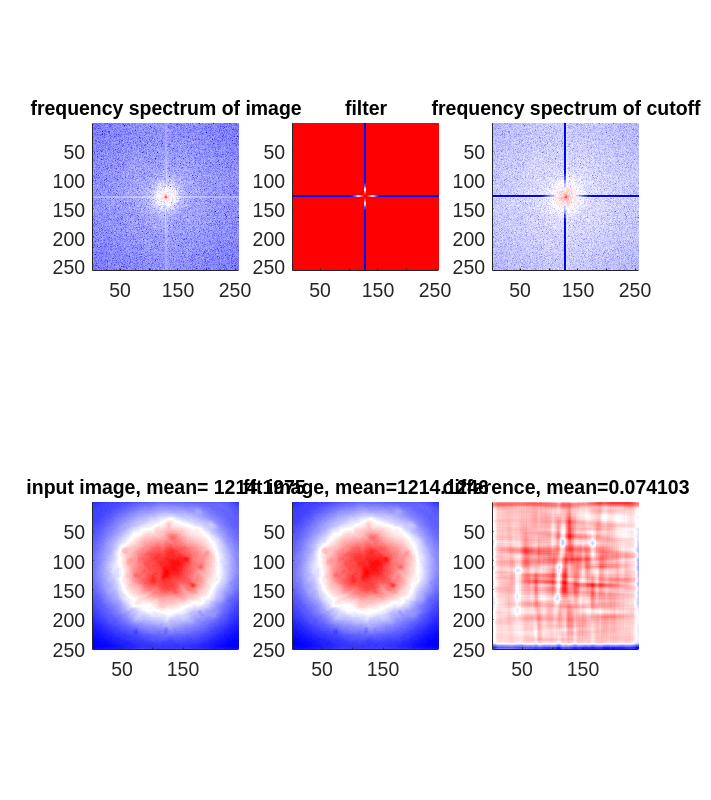

if guiEnabled==1
	% Show full filter sequence for one frame
	sopts.stripOrientation = 'both';
	sopts.meanFilterSize = 1;
	sopts.freqLowExclude = 10;
	sopts.bandpassType = 'highpass';
	ciapkg.api.removeStripsFromMovie(inputMovie(:,:,1),'options',sopts,'showImages',1);
	drawnow
end


% Run on the entire movie
inputMovie = ciapkg.api.removeStripsFromMovie(inputMovie,'options',sopts,'showImages',0);

Running stripe removal using Matlab FFT


## Detrend movie if needed (default linear trend), e.g. to compensate for bleaching over time.

inputMovie = ciapkg.api.normalizeMovie(inputMovie,'normalizationType','detrend','detrendDegree',1);

***Running normalization: detrend


## USER INTERFACE Get coordinates to crop from the user separately

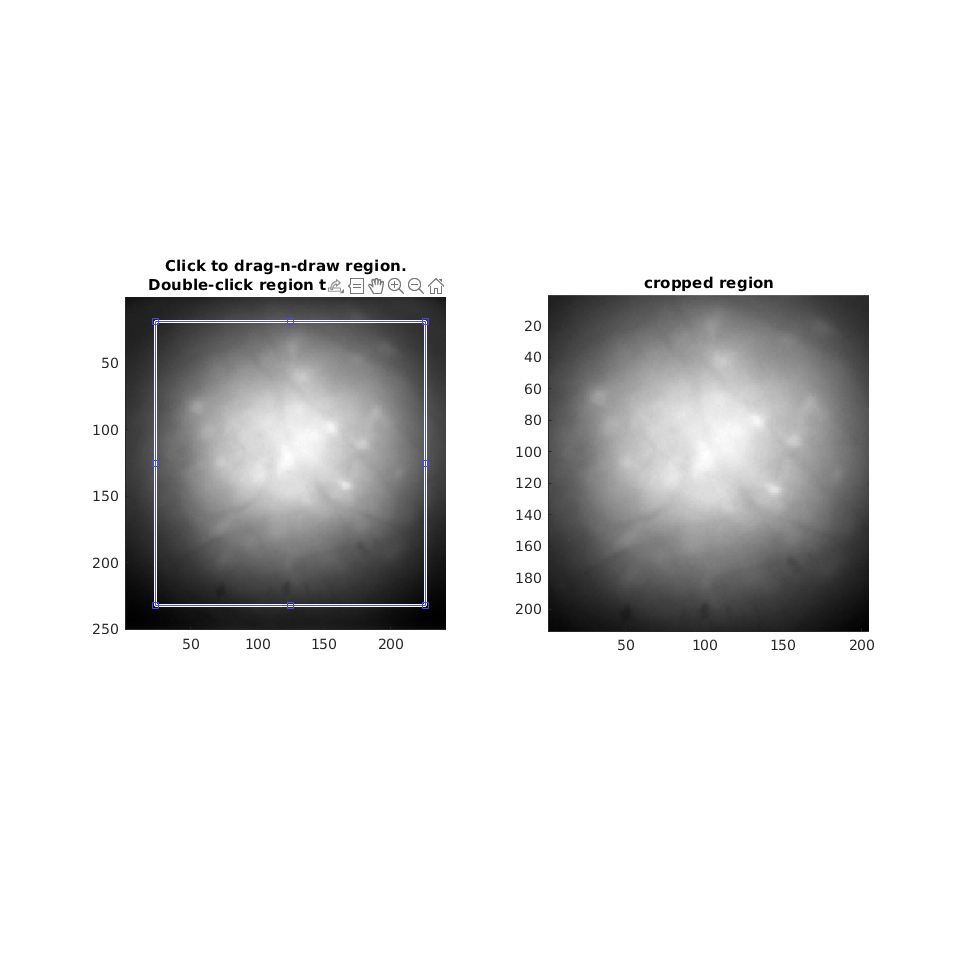

if guiEnabled==1
	[cropCoords] = ciapkg.api.getCropCoords(squeeze(inputMovie(:,:,1)));
	toptions.cropCoords = cropCoords;
	% Or have turboreg function itself directly ask the user for manual area from which to obtain correction coordinates
	% toptions.cropCoords = 'manual';
else
	toptions.cropCoords = [26 34 212 188];
end

## Pre-process movies

Motion correction

Starting motion correction (turboreg)...
cropping stack...


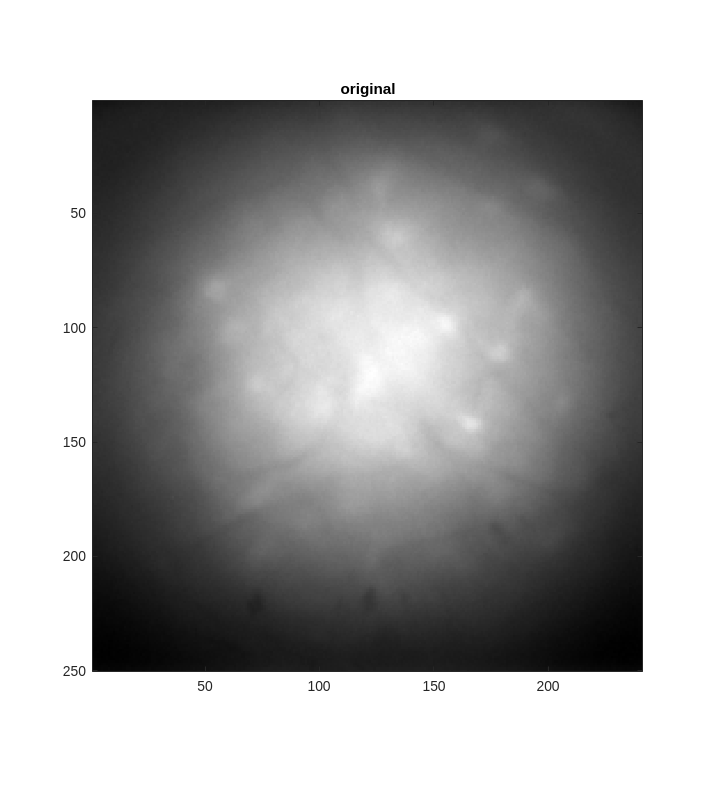

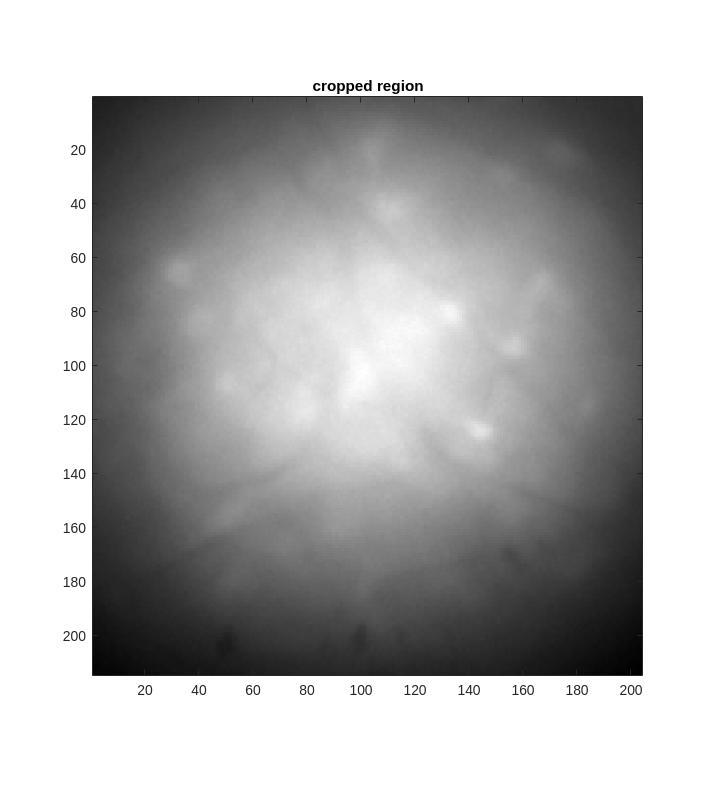

cropped dims: 250   241  3000
cropped dims: 214   204  3000
Matlab fspecial disk background removal
Finished.
mean subtracting and complementing matrix...
subtracting mean: 0|2|3|5|7|8|10|12|13|15|17|18|20|22|23|25|27|28|30|32|33|35|37|38|40|42|43|45|47|48|50|52|53|55|57|58|60|62|63|65|67|68|70|72|73|75|77|78|80|82|83|85|87|88|90|92|93|95|97|98|100
turboreg-ing...
Elapsed time is 35.227786 seconds.
dividing movie by lowpass...
***Running normalization: lowpassFFTDivisive
Running Matlab FFT
Finished.
restoring uncropped movie and converting to cell...
Elapsed time is 43.917000 seconds.
registering frames...
registering sublists: 1  1501  3000
Performing transfturboreg registration and projective transformation.
1-1500 1/2
Finished.
1501-3000 2/2
Finished.
Elapsed time is 50.021552 seconds.
converting cell array back to matrix


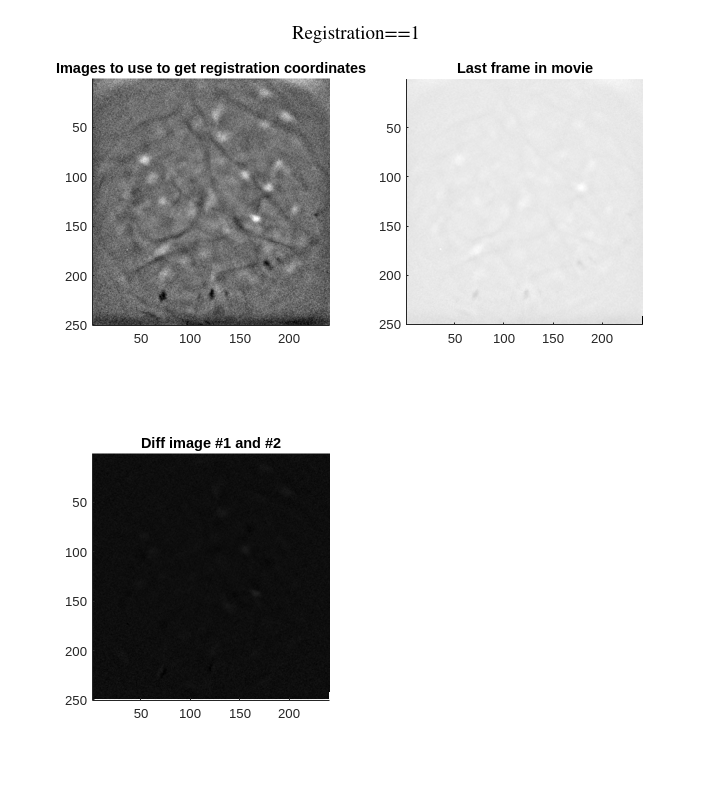

getting crop amount: 0|2|4|6|8|10|12|14|16|18|20|22|24|26|28|30|32|34|36|38|40|42|44|46|48|50|52|54|56|58|60|62|64|66|68|70|72|74|76|78|80|82|84|86|88|90|92|94|96|98|100
[topVal bottomVal leftVal rightVal]: 1  4  2  2
Elapsed time is 52.299841 seconds.


toptions.turboregRotation = 0;
toptions.removeEdges = 1;
toptions.pxToCrop = 10;
% Pre-motion correction
	toptions.complementMatrix = 1;
	toptions.meanSubtract = 1;
	toptions.meanSubtractNormalize = 1;
	toptions.normalizeType = 'matlabDisk';
% Spatial filter
	toptions.normalizeBeforeRegister = 'divideByLowpass';
	toptions.freqLow = 0;
	toptions.freqHigh = 7;
[inputMovie2, ~] = ciapkg.api.turboregMovie(inputMovie,'options',toptions);

## Compare raw and motion corrected movies

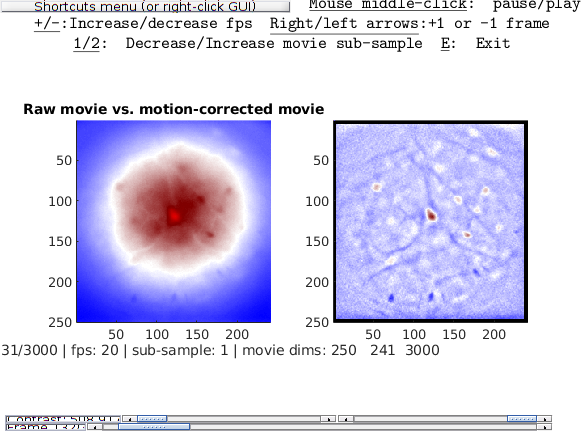

if guiEnabled==1
	ciapkg.api.playMovie(inputMovie,'extraMovie',inputMovie2,'extraTitleText','Raw movie vs. motion-corrected movie');
end

## Run dF/F

inputMovie3 = ciapkg.api.dfofMovie(single(inputMovie2),'dfofType','dfof');

Getting F0...
0%|10|20|30|40|50|60|70|80|90|100%
Calculating: F(t)/F0 - 1...


## Run temporal downsamplingat converts the sample data into 32 bit TIFF images. Currently it saves the images in the current folder. In the next version, I will 

inputMovie3 = ciapkg.api.downsampleMovie(inputMovie3,'downsampleDimension','time','downsampleFactor',4);

bilinear temporally downsampling matrix: 0|41|83| 


## USER INTERFACE Final check of movie before cell extraction

\texttt{}
\texttt{\underline{Mouse scroll wheel}: Forward/back frame
\underline{Mouse middle-click}: pause/play movie}
\texttt{\underline{+/-}:Increase/decrease fps
\underline{Right/left arrows}:+1 or -1 frame}
\texttt{\underline{1/2}: Decrease/Increase movie sub-sample
\underline{E}: Exit}



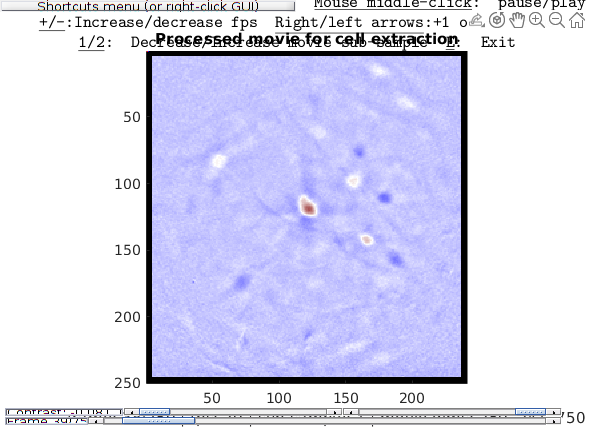

if guiEnabled==1
	ciapkg.api.playMovie(inputMovie3,'extraTitleText','Processed movie for cell extraction');
end


outputMoviePath = [analysisFolderPath filesep folderName '_spatialFiltBfReg_turboreg_crop_dfof_downsampleTime.h5'];
ciapkg.api.saveMatrixToFile(inputMovie3,outputMoviePath);

save matrix size: 250  241  750
Saving to: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/2014_04_01_p203_m19_check01_spatialFiltBfReg_turboreg_crop_dfof_downsampleTime.h5
Deleting: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/2014_04_01_p203_m19_check01_spatialFiltBfReg_turboreg_crop_dfof_downsampleTime.h5.
input class: single
creating HDF5 file: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/2014_04_01_p203_m19_check01_spatialFiltBfReg_turboreg_crop_dfof_downsampleTime.h5
writing HDF5 file: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/2014_04_01_p203_m19_check01_spatialFiltBfReg_turboreg_crop_dfof_downsampleTime.h5
success!!!
Done! Time elapsed: 5.6 seconds | 0.093 minutes 


## Run PCA-ICA cell extraction

nPCs = 300;
nICs = 225;
pcaicaStruct = ciapkg.signal_extraction.runPcaIca(inputMovie3,nPCs,nICs,'version',2,'output_units','fl','mu',0.1,'term_tol',5e-6,'max_iter',1e3);

Output argument "pcaicaAnalysisOutput" (and possibly others) not assigned a value in the execution with "ciapkg.signal_extraction.runPcaIca" function.

## Save outputs to NWB format

mkdir([analysisFolderPath filesep 'nwbFiles']);

if saveAnalysis==1
	ciapkg.api.saveNeurodataWithoutBorders(pcaicaStruct.IcaFilters,{pcaicaStruct.IcaTraces},'pcaica',[nwbFilePath '_pcaicaAnalysis.nwb']);
end

Unable to resolve the name pcaicaStruct.IcaFilters.

## Run CNMF or CNMF-e cell extraction

numExpectedComponents = 225;
cellWidth = 10;
cnmfOptions.otherCNMF.tau = cellWidth/2; % expected width of cells

% Run CNMF
[success] = ciapkg.api.cnmfVersionDirLoad('current');

Add /home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current


Dialog box: select cvx_setup.m.
@@@@@@@
Error using run (line 46)
 /  not found.

Error in ciapkg.signal_extraction.runCvxSetup (line 42)
			run([folderPath filesep filePath]);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('ciapkg.api.runCvxSetup', '/home/user1/Documents/Manisha/ciatah-master/+ciapkg/+api/runCvxSetup.m', 15)" style="font-weigh

starting resampling 
Initializing components with greedy method 
found 10 out of 225 neurons..
found 20 out of 225 neurons..
found 30 out of 225 neurons..
found 40 out of 225 neurons..
found 50 out of 225 neurons..
found 60 out of 225 neurons..
found 70 out of 225 neurons..
found 80 out of 225 neurons..
found 90 out of 225 neurons..
found 100 out of 225 neurons..
found 110 out of 225 neurons..
found 120 out of 225 neurons..
found 130 out of 225 neurons..
found 140 out of 225 neurons..
found 150 out of 225 neurons..
found 160 out of 225 neurons..
found 170 out of 225 neurons..
found 180 out of 225 neurons..
found 190 out of 225 neurons..
found 200 out of 225 neurons..
found 210 out of 225 neurons..
found 220 out of 225 neurons..
Refining initial estimates with HALS...  done 


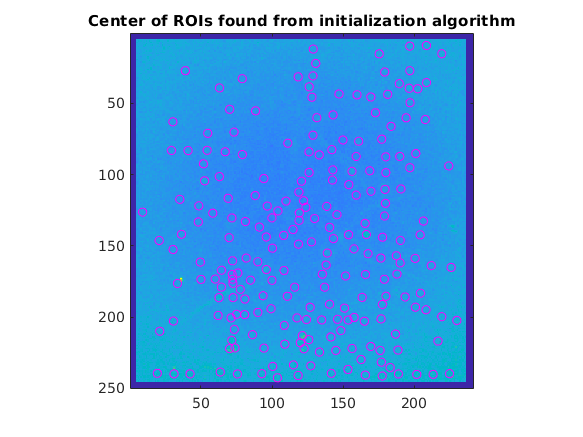

Updated spatial components 
113 out of 225 components updated 
187 out of 225 components updated 
215 out of 225 components updated 
225 out of 225 components updated 
113 out of 225 components updated 
187 out of 225 components updated 
215 out of 225 components updated 
225 out of 225 components updated 


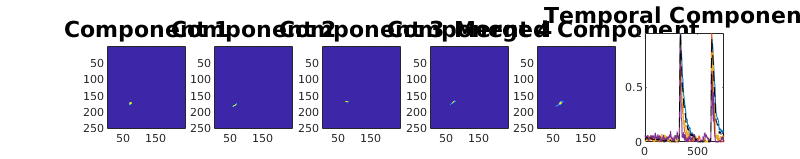

Updated spatial components 
75 out of 106 components updated 
101 out of 106 components updated 
105 out of 106 components updated 
106 out of 106 components updated 
75 out of 106 components updated 
101 out of 106 components updated 
105 out of 106 components updated 
106 out of 106 components updated 
Organizing output struct...


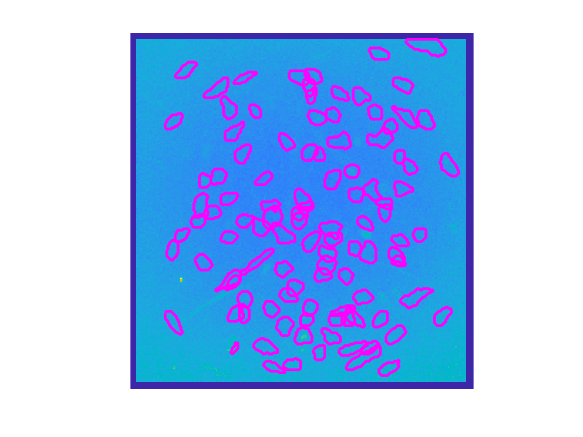

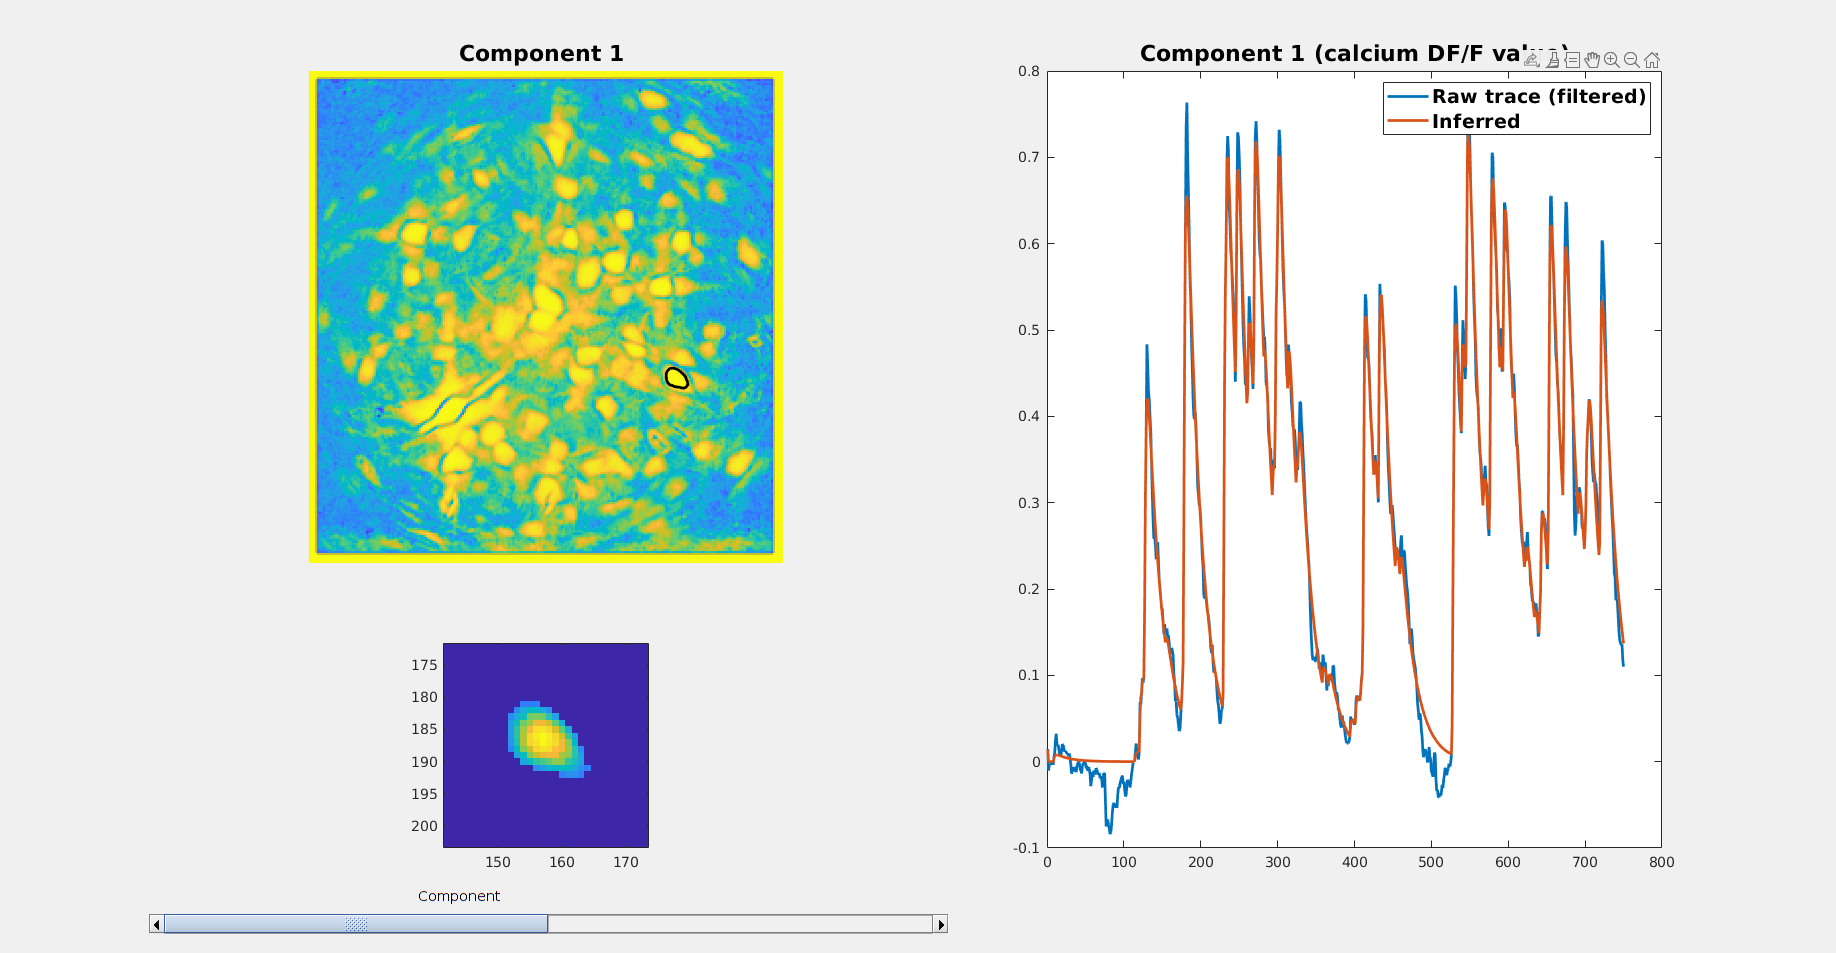

[cnmfAnalysisOutput] = ciapkg.api.computeCnmfSignalExtractionClass(inputMovie3,numExpectedComponents,'options',cnmfOptions);


% Run CNMF-e
[success] = ciapkg.api.cnmfVersionDirLoad('cnmfe');

    {'/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/3D:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/Sources2D:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/deconvolution:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/deconvolution/MCMC:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/deconvolution/MCMC/utilities:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/deconvolution/examples:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/deconvolution/functions:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/deconvolution/oasis:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/docs:/home/user1/Documents/Manisha/ciatah-master/_external_programs/cnmf_current/docs/notes:

cnmfeOptions.gSiz = cellWidth;
cnmfeOptions.gSig = ceil(cellWidth/4);
[cnmfeAnalysisOutput] = ciapkg.api.computeCnmfeSignalExtraction_batch(outputMoviePath,'options',cnmfeOptions);

Running CNMF-e batch wrapper script
options:
                    nonCNMF: [1×1 struct]
                   runMerge: 1
    runRemoveFalsePositives: 1
         memory_size_to_use: 8
      memory_size_per_patch: 0.6000
                 patch_dims: [64 64]
               batch_frames: 5000
                       gSig: 3
                       gSiz: 10
                       ssub: 1
             with_dendrites: 1
               updateA_bSiz: 5
          spatial_algorithm: 'hals_thresh'
                       tsub: 1
                         Fs: 10
                deconv_smin: -5
                    max_tau: 100
                         nk: 3
                   bg_model: 'ring'
                         nb: 1
                ring_radius: 18
                    bg_ssub: 2
                  merge_thr: 0.6500
                method_dist: 'max'
                       dmin: 5
                  dmin_only: 2
          merge_thr_spatial: [0.8000 0.4000 -Inf]
                    

Output argument "cnmfeAnalysisOutput" (and possibly others) not assigned a value in the execution with "ciapkg.signal_extraction.computeCnmfeSignalExtraction_batch" function.

Error in ciapkg.api.computeCnmfeSignalExtraction_batch (line 20)
	[cnmfeAnalysisOutput] = ciapkg.signal_extraction.computeCnmfeSignalExtraction_batch(inputMovie,'passArgs', varargin);


% Save outputs to NWB format
if saveAnalysis==1
	% Save CNMF
	ciapkg.api.saveNeurodataWithoutBorders(cnmfAnalysisOutput.extractedImages,{cnmfAnalysisOutput.extractedSignals,cnmfAnalysisOutput.extractedSignalsEst},'cnmf',[nwbFilePath '_cnmf.nwb']);

	% Save CNMF-E
	ciapkg.api.saveNeurodataWithoutBorders(cnmfeAnalysisOutput.extractedImages,{cnmfeAnalysisOutput.extractedSignals,cnmfeAnalysisOutput.extractedSignalsEst},'cnmfe',[nwbFilePath '_cnmfe.nwb']);
end

% Unload CNMF(-E) directories to keep namespace clean
[success] = ciapkg.api.cnmfVersionDirLoad('none');


## Run EXTRACT cell extraction. Check each function with "edit" for options.

Load default configuration

ciapkg.loadBatchFxns('loadEverything');

MATALB path already has all needed non-private folders under: /home/user1/Documents/Manisha/ciatah-master
ImageJ already loaded!
Skipping loading of Miji.


extractConfig = get_defaults([]);

% See https://github.com/schnitzer-lab/EXTRACT-public#configurations.
cellWidth = 10;
extractConfig.avg_cell_radius = cellWidth;
extractConfig.num_partitions_x = 2;
extractConfig.num_partitions_y = 2;
extractConfig.use_sparse_arrays = 0;

outStruct = extractor(inputMovie3,extractConfig);

15-Dec-2021 18:48:36: Getting GPU information... 
	 	 	 GPU Device 1 - GeForce GTX 1050 Ti: Available Memory: 2.9 Gb
	 	 	 - Selecting GPU device 1 
15-Dec-2021 18:48:38: Signal extraction on partition 4 (of 4):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0006 
	 	 	 	 minimum magnitude: 0.0007 
			 Step #100, found 98 cells... 
			 Step #200, found 187 cells... 
			 Step #300, found 254 cells... 
	 	 	 291 cells found after a total of 369 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 174 (117 removed) 
	 	 	 End of iter # 2: # cells: 148 (26 removed) 
	 	 	 End of iter # 3: # cells: 139 (9 removed) 
	 	 	 End of iter # 4: # cells: 132 (7 removed) 
	 	 	 End of iter # 5: # cells: 127 (5 removed) 
	 	 	 End of iter # 6: # cells: 121 (6 removed) 
	 	 


% Grab outputs and put into standard format
extractAnalysisOutput.filters = outStruct.spatial_weights;
% permute so it is [nCells frames]
extractAnalysisOutput.traces = permute(outStruct.temporal_weights, [2 1]);

% Other run information if saving as a MAT-file.
extractAnalysisOutput.info = outStruct.info;
extractAnalysisOutput.config = outStruct.config;
extractAnalysisOutput.info = outStruct.info;
extractAnalysisOutput.userInputConfig = extractConfig;
extractAnalysisOutput.opts = outStruct.config;

% Save outputs to NWB format
if saveAnalysis==1
	ciapkg.api.saveNeurodataWithoutBorders(extractAnalysisOutput.filters,{extractAnalysisOutput.traces},'extract',[nwbFilePath '_extract.nwb']);
end

NWB dependencies loaded.
NWB Schema types already loaded!
Directory already exists: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles.
Input images size: 250  241  372
Input traces #1 size: 372  750


Deleting /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles/2014_04_01_p203_m19_check01_extract.nwb.
Saving to: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles/2014_04_01_p203_m19_check01_extract.nwb.
Done saving to NWB!



% Remove EXTRACT from the path.
ciapkg.loadBatchFxns();

Folders still need to be removed.
ImageJ already loaded!
Skipping loading of Miji.


## USER INTERFACE Run cell sorting using matrix outputs from cell extraction.

if guiEnabled==1
	[outImages, outSignals, choices] = ciapkg.api.signalSorter(pcaicaStruct.IcaFilters,pcaicaStruct.IcaTraces,'inputMovie',inputMovie3);

	% Plot results of sorting
	figure;
	subplot(1,2,1);imagesc(max(IcaFilters,[],3));axis equal tight; title('Raw filters')
	subplot(1,2,2);imagesc(max(outImages,[],3));axis equal tight; title('Sorted filters')
end

Unable to resolve the name pcaicaStruct.IcaFilters.

## Run signal sorting using NWB

[outImages, outSignals, choices] = ciapkg.api.signalSorter([nwbFilePath '_pcaicaAnalysis.nwb'],[],'inputMovie',inputMovie3);

options = struct with fields:
                         inputMovie: [250×241×750 single]
                 inputSignalsSecond: []
                          signalSnr: []
                      inputMovieRaw: []
                              coord: [1×1 struct]
                              valid: 'neutralStart'
               peakTrigMovieMontage: 1
                       nMovieFrames: 10
                     inputMovieDims: []
                   inputDatasetName: '/1'
                            hdf5Fid: []
                       keepFileOpen: 0
                          frameList: []
             nFrameSampleInputMovie: 10
           fractionSampleInputMovie: 0.0100
                    readMovieChunks: 0
                           movieMax: NaN
                           movieMin: NaN
                        movieMinLim: -0.0200
                          movieMean: NaN
           preComputeImageCutMovies: 0
                  nSignalsLoadAsync: 20
                   maxSignalsToShow: 15


Loading NWB file.
NWB dependencies loaded.
NWB Schema types already loaded!
Loading: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles/2014_04_01_p203_m19_check01_pcaicaAnalysis.nwb file -> /processing/ophys/ImageSegmentation/PlaneSegmentation/image_mask.
@@@@@@@
Error using h5readc
Unable to open '/home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles/2014_04_01_p203_m19_check01_pcaicaAnalysis.nwb'. File or folder not found.

Error in h5read (line 93)
[data,var_class] = h5readc(Filename,Dataset,start,count,stride);

Error in <a href="mat

Output argument "choices" (and possibly others) not assigned a value in the execution with "ciapkg.classification.signalSorter" function.

Error in ciapkg.api.signalSorter (line 19)
	[inputImages, inputSignals, choices] = ciapkg.classification.signalSorter(inputImages,inputSignals,'passArgs', varargin);

## USER INTERFACE Run signal sorting using multiple NWB files from cell extraction.

if saveAnalysis==1&guiEnabled==1
	disp(repmat('=',1,21));disp('Running signalSorter using NWB file input.')
	nwbFileList = ciapkg.api.getFileList(nwbFileFolderPath,'.nwb');
	if ~isempty(nwbFileList)
		nFiles = length(nwbFileList);
		outImages = {};
		outSignals = {};
		choices = {};
		for fileNo = 1:nFiles
			[outImages{fileNo}, outSignals{fileNo}, choices{fileNo}] = ciapkg.api.signalSorter(nwbFileList{fileNo},[],'inputMovie',inputMovie3);
		end

		% Plot results of sorting
		for fileNo = 1:nFiles
			try
				[inputImagesTmp,inputSignalsTmp,infoStructTmp,algorithmStrTmp,inputSignals2Tmp] = ciapkg.api.loadSignalExtraction(nwbFileList{fileNo});
				figure;
				subplot(1,2,1); 
					imagesc(max(inputImagesTmp,[],3));
					axis equal tight; 
					title([algorithmStrTmp ' | Raw filters'])
				subplot(1,2,2); 
					imagesc(max(outImages{fileNo},[],3));
					axis equal tight; 
					title('Sorted filters')
			catch err
				disp(repmat('@',1,7))
				disp(getReport(err,'extended','hyperlinks','on'));
				disp(repmat('@',1,7))
			end
		end
	end
end

Running signalSorter using NWB file input.


options = struct with fields:
                         inputMovie: [250×241×750 single]
                 inputSignalsSecond: []
                          signalSnr: []
                      inputMovieRaw: []
                              coord: [1×1 struct]
                              valid: 'neutralStart'
               peakTrigMovieMontage: 1
                       nMovieFrames: 10
                     inputMovieDims: []
                   inputDatasetName: '/1'
                            hdf5Fid: []
                       keepFileOpen: 0
                          frameList: []
             nFrameSampleInputMovie: 10
           fractionSampleInputMovie: 0.0100
                    readMovieChunks: 0
                           movieMax: NaN
                           movieMin: NaN
                        movieMinLim: -0.0200
                          movieMean: NaN
           preComputeImageCutMovies: 0
                  nSignalsLoadAsync: 20
                   maxSignalsToShow: 15


Loading NWB file.
NWB dependencies loaded.
NWB Schema types already loaded!
Loading: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles/2014_04_01_p203_m19_check01_extract.nwb file -> /processing/ophys/ImageSegmentation/PlaneSegmentation1/image_mask.
Loading: /home/user1/Documents/Manisha/ciatah-master/data/2014_04_01_p203_m19_check01/nwbFiles/2014_04_01_p203_m19_check01_extract.nwb file -> /processing/ophys/Fluorescence/RoiResponseSeries1/data.
inputImages: 250  241  372
inputTraces: 372  750
inputImages size: 250  241  372
inputSignals size: 372  750
Number of signals or cells in input images (372) and activity traces (372) DO match. Continuing...


## USER INTERFACE Create an overlay of extraction outputs on the movie and signal-based movie

[inputMovieO] = ciapkg.api.createImageOutlineOnMovie(inputMovie3,IcaFilters,'dilateOutlinesFactor',0);
if guiEnabled==1
	ciapkg.api.playMovie(inputMovieO,'extraMovie',inputMovie3,'extraTitleText','Overlay of cell outlines on processed movie');
end

[signalMovie] = ciapkg.api.createSignalBasedMovie(IcaTraces,IcaFilters,'signalType','peak');
if guiEnabled==1
	ciapkg.api.playMovie(signalMovie,'extraMovie',inputMovie3,'extraTitleText','Cell activity-based movie');
end

movieM = cellfun(@(x) ciapkg.api.normalizeVector(x,'normRange','zeroToOne'),{inputMovie3,inputMovieO,signalMovie},'UniformOutput',false);
ciapkg.api.playMovie(cat(2,movieM{:}));


## Run pre-processing on 3 batch movies then do cross-session alignment

batchMovieList = {...
[ciapkg.getDir() filesep 'data' filesep 'batch' filesep '2014_08_05_p104_m19_PAV08'],...
[ciapkg.getDir() filesep 'data' filesep 'batch' filesep '2014_08_06_p104_m19_PAV09'],...
[ciapkg.getDir() filesep 'data' filesep 'batch' filesep '2014_08_07_p104_m19_PAV10']...
};

% USER INTERFACE Get the motion correction crop coordinates
cropCoordsCell = {};
nFolders = length(batchMovieList);
for folderNo = 1:nFolders
	analysisFolderPath = batchMovieList{folderNo};
	inputMoviePath = ciapkg.api.getFileList(analysisFolderPath,rawFileRegexp,'sortMethod','natural');
	% inputMoviePath = [analysisFolderPath filesep 'concat_recording_20140401_180333.h5'];
	inputMovie = ciapkg.api.loadMovieList(inputMoviePath,'inputDatasetName',inputDatasetName,'frameList',1:2);

	[cropCoords] = ciapkg.api.getCropCoords(squeeze(inputMovie(:,:,1)));
	% toptions.cropCoords = cropCoords;
	cropCoordsCell{folderNo} = cropCoords;
end

## Run pre-processing on each of the movies.

procMovieCell = cell([1 nFolders]);
for folderNo = 1:nFolders
	inputMoviePath = ciapkg.api.getFileList(analysisFolderPath,rawFileRegexp,'sortMethod','natural');
	inputMovie = ciapkg.api.loadMovieList(inputMoviePath,'inputDatasetName',inputDatasetName,'frameList',[]);
	procOpts.motionCorrectionCropCoords = cropCoordsCell{folderNo};
	procOpts.dfofMovie = 1;
	procOpts.motionCorrectionFlag = 1;
	procOpts.normalizeMovieFlag = 1;
	procOpts.normalizeType = 'divideByLowpass';
	procOpts.freqLow = 0;
	procOpts.freqHigh = 7;
	procOpts.downsampleTimeFactor = 4;
	procMovieCell{folderNo} = ciapkg.demo.runPreprocessing(inputMovie,'options',procOpts);
end
disp('Done with pre-processing!')

## Run cell-extraction on the movies

pcaicaStructCell = cell([1 nFolders]);
nPCs = 300;
nICs = 225;
for folderNo = 1:nFolders
	inputMoviePath = ciapkg.api.getFileList(analysisFolderPath,rawFileRegexp,'sortMethod','natural');
	pcaicaStruct{folderNo} = ciapkg.signal_extraction.runPcaIca(procMovieCell{folderNo},nPCs,nICs,'version',2,'outputUnits','fl','mu',0.1,'term_tol',5e-6,'max_iter',1e3);
end
disp('Done with PCA-ICA analysis pre-processing!')

## Run cross-session alignment of cells

Create input images, cell array of [x y nCells] matrices

inputImages = cellfun(@(x) x.IcaFilters,pcaicaStruct,'UniformOutput',false);

% options to change
opts.maxDistance = 5; % distance in pixels between centroids for them to be grouped
opts.trialToAlign = 1; % which session to start alignment on
opts.nCorrections = 1; %number of rounds to register session cell maps.
opts.RegisTypeFinal = 2; % 3 = rotation/translation and iso scaling; 2 = rotation/translation, no iso scaling

% Run alignment code
[alignmentStruct] = ciapkg.api.matchObjBtwnTrials(inputImages,'options',opts);

% Global IDs is a matrix of [globalID sessionID]
% Each (globalID, sessionID) pair gives the within session ID for that particular global ID
globalIDs = alignmentStruct.globalIDs;

% View the cross-session matched cells, saved to `private\_tmpFiles` sub-folder.
[success] = ciapkg.api.createMatchObjBtwnTrialsMaps(inputImages,alignmentStruct);

## Display cross-session matching movies

disp('Playing movie frames')
crossSessionMovie1 = [ciapkg.getDir filesep 'private' filesep '_tmpFiles' filesep 'matchObjColorMap50percentMatchedSession_matchedCells.avi'];
crossSessionMovie2 = [ciapkg.getDir filesep 'private' filesep '_tmpFiles' filesep 'matchObjColorMapAllMatchedSession_matchedCells.avi'];
ciapkg.api.playMovie(crossSessionMovie1,'extraMovie',crossSessionMovie2,'rgbDisplay',1);